clear
load data2.mat
n=length(data.CzasLokalnyUTC0000)

n = 516459

Given from Data2Analysis

T=5; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Skraplacz=0.1*data.Skraplacz;
Kompresor1=data.Kompresor1;
Parownik1=0.1*data.Parownik1;
Wlot=0.1*data.Wlot;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Rozmraanie=data.Rozmraanie;
WentylatorParownika=data.WentylatorParownika;
ZawrOdszraniania=data.ZawrOdszraniania;

X_all=[ZawrOdszraniania,Kompresor1,WentylatorParownika,Rozmraanie,...
    TemperaturaOtoczenia,Skraplacz,Wlot,Parownik1]';

[X,~]  = GetRidOfNans(X_all);

Let's take 5h from 10-15th hour of the first day (time between defrosting cycles) because it is an example of normal operation

h10th=10*60*60*fs

h10th = 7200

h15th=15*60*60*fs

h15th = 10800


t=T*(h10th:h15th);
X=X';
X=X(:,h10th:h15th);
size(X)

ans =            8        3601


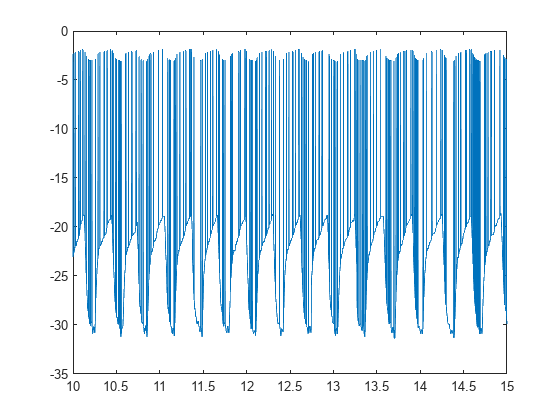

plot(t/(60*60),X(8,:))

Data interpolation to remove errors

X_toFilter=X(5:8,:);
threshold=[0,5;0,5;-5,0;-5,0]

threshold =      0     5
     0     5
    -5     0
    -5     0


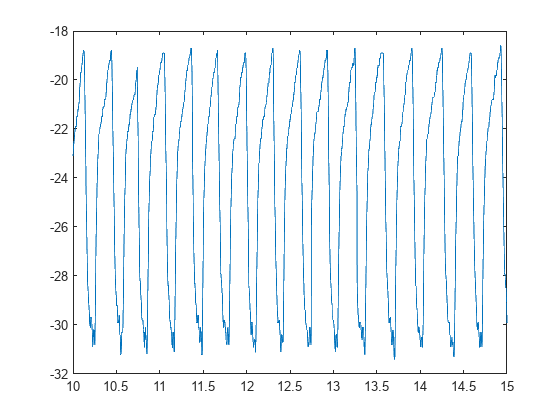

for i = 1:4
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end
plot(t/(60*60),X_filtered(4,:))

Example of model behaviour

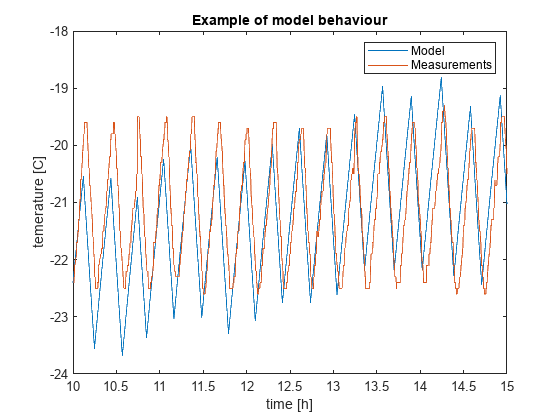

x=X(2,:);
y=X_filtered(3,:);
Ta=X_filtered(1,:);

R=-99;
C=-98;
G=-1.07;
x0=y(1);
y1=ModelFunction(-x',Ta',G,R,C,t,x0);

plot(t/(60*60),y1,'-'); hold on
plot(t/(60*60),y,'-');hold off
title('Example of model behaviour')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Model','Measurements')